### Offset Correction vs No Correction

clear all; close all; clc;

% No correction no LTE
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid/s6/mabs_i1_c0_l0.mat')
dphase_1_0_0.lls = error_lls;
dphase_1_0_0.nlls = error_nlls;
[dphase_1_0_0.F_lls, dphase_1_0_0.X_lls] = ecdf(error_lls);
[dphase_1_0_0.F_nlls, dphase_1_0_0.X_nlls] = ecdf(error_nlls);

% Correction no LTE
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid/s6/mabs_i1_c1_l0.mat')
dphase_1_1_0.lls = error_lls;
dphase_1_1_0.nlls = error_nlls;
[dphase_1_1_0.F_lls, dphase_1_1_0.X_lls] = ecdf(error_lls);
[dphase_1_1_0.F_nlls, dphase_1_1_0.X_nlls] = ecdf(error_nlls);

% Correction with LTE
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid/s6/mabs_i1_c1_l1.mat')
dphase_1_1_1.lls = error_lls;
dphase_1_1_1.nlls = error_nlls;
[dphase_1_1_1.F_lls, dphase_1_1_1.X_lls] = ecdf(error_lls);
[dphase_1_1_1.F_nlls, dphase_1_1_1.X_nlls] = ecdf(error_nlls);

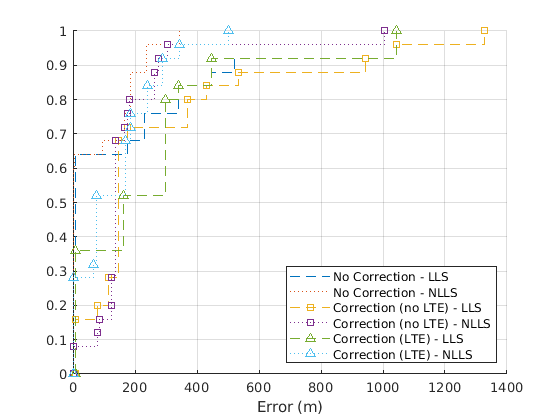

% Plotting
figure(); hold on; grid on;
stairs(dphase_1_0_0.X_lls, dphase_1_0_0.F_lls, '--');
stairs(dphase_1_0_0.X_nlls, dphase_1_0_0.F_nlls, ':');
stairs(dphase_1_1_0.X_lls, dphase_1_1_0.F_lls, '--s');
stairs(dphase_1_1_0.X_nlls, dphase_1_1_0.F_nlls, ':s');
stairs(dphase_1_1_1.X_lls, dphase_1_1_1.F_lls, '--^');
stairs(dphase_1_1_1.X_nlls, dphase_1_1_1.F_nlls, ':^');
legend('No Correction - LLS', 'No Correction - NLLS', 'Correction (no LTE) - LLS', 'Correction (no LTE) - NLLS', 'Correction (LTE) - LLS', 'Correction (LTE) - NLLS','Location','southeast');
xlabel('Error (m)');

% Plotting
figure(); hold on; grid on;
stairs(dphase_1_1_0.X_lls, dphase_1_1_0.F_lls, '--s');
stairs(dphase_1_1_0.X_nlls, dphase_1_1_0.F_nlls, ':s');
stairs(dphase_1_1_1.X_lls, dphase_1_1_1.F_lls, '--^');
stairs(dphase_1_1_1.X_nlls, dphase_1_1_1.F_nlls, ':^');
legend('Correction (no LTE) - LLS', 'Correction (no LTE) - NLLS', 'Correction (LTE) - LLS', 'Correction (LTE) - NLLS','Location','southeast');
xlabel('Error (m)'); 

### Interpolation vs No Interpolation

% Interp 1
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid/s4/mdphase_i1_c1_l1.mat')
dphase_1_1_1.lls = error_lls;
dphase_1_1_1.nlls = error_nlls;
[dphase_1_1_1.F_lls, dphase_1_1_1.X_lls] = ecdf(error_lls);
[dphase_1_1_1.F_nlls, dphase_1_1_1.X_nlls] = ecdf(error_nlls);

% Interp 5
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid/s4/mdphase_i5_c1_l1.mat')
dphase_5_1_1.lls = error_lls;
dphase_5_1_1.nlls = error_nlls;
[dphase_5_1_1.F_lls, dphase_5_1_1.X_lls] = ecdf(error_lls);
[dphase_5_1_1.F_nlls, dphase_5_1_1.X_nlls] = ecdf(error_nlls);

% Interp 10
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid/s4/mdphase_i10_c1_l1.mat')
dphase_10_1_1.lls = error_lls;
dphase_10_1_1.nlls = error_nlls;
[dphase_10_1_1.F_lls, dphase_10_1_1.X_lls] = ecdf(error_lls);
[dphase_10_1_1.F_nlls, dphase_10_1_1.X_nlls] = ecdf(error_nlls);

% Interp 20
% Correction with LTE
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid/s4/mdphase_i20_c1_l1.mat')
dphase_20_1_1.lls = error_lls;
dphase_20_1_1.nlls = error_nlls;
[dphase_20_1_1.F_lls, dphase_20_1_1.X_lls] = ecdf(error_lls);
[dphase_20_1_1.F_nlls, dphase_20_1_1.X_nlls] = ecdf(error_nlls);

% Interp 50
% Correction with LTE
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid/s4/mdphase_i50_c1_l1.mat')
dphase_50_1_1.lls = error_lls;
dphase_50_1_1.nlls = error_nlls;
[dphase_50_1_1.F_lls, dphase_50_1_1.X_lls] = ecdf(error_lls);
[dphase_50_1_1.F_nlls, dphase_50_1_1.X_nlls] = ecdf(error_nlls);

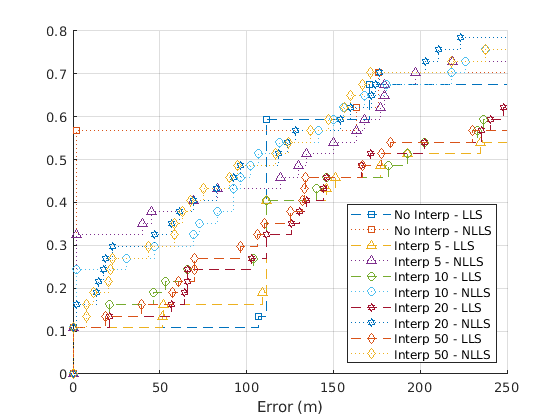

% Plotting
figure(); hold on; grid on;
stairs(dphase_1_1_1.X_lls, dphase_1_1_1.F_lls, '--s');
stairs(dphase_1_1_1.X_nlls, dphase_1_1_1.F_nlls, ':s');
stairs(dphase_5_1_1.X_lls, dphase_5_1_1.F_lls, '--^');
stairs(dphase_5_1_1.X_nlls, dphase_5_1_1.F_nlls, ':^');
stairs(dphase_10_1_1.X_lls, dphase_10_1_1.F_lls, '--o');
stairs(dphase_10_1_1.X_nlls, dphase_10_1_1.F_nlls, ':o');
stairs(dphase_20_1_1.X_lls, dphase_20_1_1.F_lls, '--h');
stairs(dphase_20_1_1.X_nlls, dphase_20_1_1.F_nlls, ':h');
stairs(dphase_50_1_1.X_lls, dphase_50_1_1.F_lls, '--d');
stairs(dphase_50_1_1.X_nlls, dphase_50_1_1.F_nlls, ':d');
legend('No Interp - LLS', 'No Interp - NLLS', 'Interp 5 - LLS', 'Interp 5 - NLLS', 'Interp 10 - LLS', ...
    'Interp 10 - NLLS', 'Interp 20 - LLS', 'Interp 20 - NLLS','Interp 50 - LLS', 'Interp 50 - NLLS','Location','southeast');
xlabel('Error (m)');
xlim([0,250]);

### Interpolation vs No Interpolation (abs)

% Interp 1
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid/s6/mabs_i1_c1_l1.mat')
abs_1_1_1.lls = error_lls;
abs_1_1_1.nlls = error_nlls;
[abs_1_1_1.F_lls, abs_1_1_1.X_lls] = ecdf(error_lls);
[abs_1_1_1.F_nlls, abs_1_1_1.X_nlls] = ecdf(error_nlls);

% Interp 5
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid/s6/mabs_i5_c1_l1.mat')
abs_5_1_1.lls = error_lls;
abs_5_1_1.nlls = error_nlls;
[abs_5_1_1.F_lls, abs_5_1_1.X_lls] = ecdf(error_lls);
[abs_5_1_1.F_nlls, abs_5_1_1.X_nlls] = ecdf(error_nlls);

% Interp 10
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid/s6/mabs_i10_c1_l1.mat')
abs_10_1_1.lls = error_lls;
abs_10_1_1.nlls = error_nlls;
[abs_10_1_1.F_lls, abs_10_1_1.X_lls] = ecdf(error_lls);
[abs_10_1_1.F_nlls, abs_10_1_1.X_nlls] = ecdf(error_nlls);

% Interp 20
% Correction with LTE
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid/s6/mabs_i20_c1_l1.mat')
abs_20_1_1.lls = error_lls;
abs_20_1_1.nlls = error_nlls;
[abs_20_1_1.F_lls, abs_20_1_1.X_lls] = ecdf(error_lls);
[abs_20_1_1.F_nlls, abs_20_1_1.X_nlls] = ecdf(error_nlls);

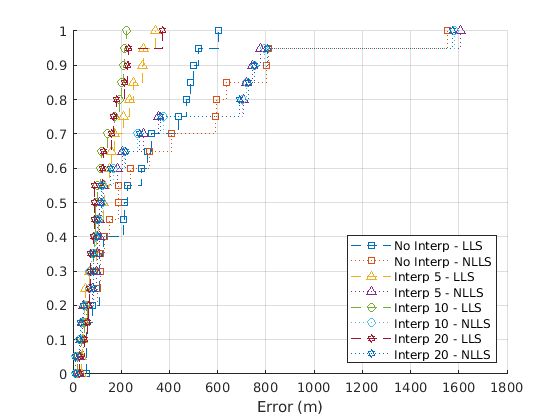

% Plotting
figure(); hold on; grid on;
stairs(abs_1_1_1.X_lls, abs_1_1_1.F_lls, '--s');
stairs(abs_1_1_1.X_nlls, abs_1_1_1.F_nlls, ':s');
stairs(abs_5_1_1.X_lls, abs_5_1_1.F_lls, '--^');
stairs(abs_5_1_1.X_nlls, abs_5_1_1.F_nlls, ':^');
stairs(abs_10_1_1.X_lls, abs_10_1_1.F_lls, '--o');
stairs(abs_10_1_1.X_nlls, abs_10_1_1.F_nlls, ':o');
stairs(abs_20_1_1.X_lls, abs_20_1_1.F_lls, '--h');
stairs(abs_20_1_1.X_nlls, abs_20_1_1.F_nlls, ':h');
legend('No Interp - LLS', 'No Interp - NLLS', 'Interp 5 - LLS', 'Interp 5 - NLLS', 'Interp 10 - LLS', 'Interp 10 - NLLS', 'Interp 20 - LLS', 'Interp 20 - NLLS','Location','southeast');
xlabel('Error (m)');

xlim([0,200]);

### abs/dphase/iq

% abs
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid/s6/mabs_i5_c1_l1.mat')
abs_1_1_1.lls = error_lls;
abs_1_1_1.nlls = error_nlls;
[abs_1_1_1.F_lls, abs_1_1_1.X_lls] = ecdf(error_lls);
[abs_1_1_1.F_nlls, abs_1_1_1.X_nlls] = ecdf(error_nlls);

% dphase
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid/s6/mdphase_i5_c1_l1.mat')
dphase_1_1_1.lls = error_lls;
dphase_1_1_1.nlls = error_nlls;
[dphase_1_1_1.F_lls, dphase_1_1_1.X_lls] = ecdf(error_lls);
[dphase_1_1_1.F_nlls, dphase_1_1_1.X_nlls] = ecdf(error_nlls);

% iq
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid/s6/miq_i5_c1_l1.mat')
iq_1_1_1.lls = error_lls;
iq_1_1_1.nlls = error_nlls;
[iq_1_1_1.F_lls, iq_1_1_1.X_lls] = ecdf(error_lls);
[iq_1_1_1.F_nlls, iq_1_1_1.X_nlls] = ecdf(error_nlls);

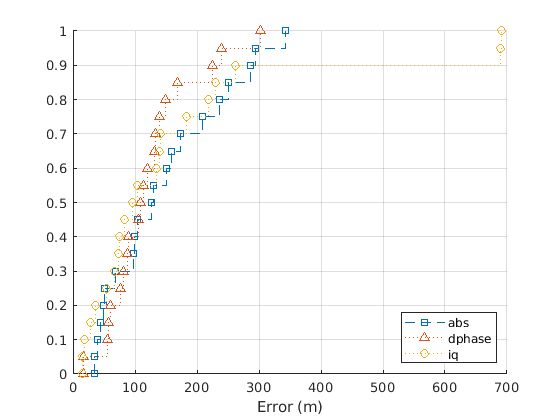

% Plotting
figure(); hold on; grid on;
stairs(abs_1_1_1.X_lls, abs_1_1_1.F_lls, '--s');
stairs(dphase_1_1_1.X_nlls, dphase_1_1_1.F_nlls, ':^');
stairs(iq_1_1_1.X_nlls, iq_1_1_1.F_nlls, ':o');
legend('abs','dphase', 'iq', 'Location','southeast');
xlabel('Error (m)');

### Original - Mean - FOC - NLLS - Upsample

% No correction
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid/s6/mdphase_i1_c0_l0.mat')
dphase_1_0_0.lls = error_lls;
dphase_1_0_0.nlls = error_nlls;
[dphase_1_0_0.F_lls, dphase_1_0_0.X_lls] = ecdf(error_lls);
[dphase_1_0_0.F_nlls, dphase_1_0_0.X_nlls] = ecdf(error_nlls);

% Correction no LTE
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid/s6/mdphase_i1_c1_l0.mat')
dphase_1_1_0.lls = error_lls;
dphase_1_1_0.nlls = error_nlls;
[dphase_1_1_0.F_lls, dphase_1_1_0.X_lls] = ecdf(error_lls);
[dphase_1_1_0.F_nlls, dphase_1_1_0.X_nlls] = ecdf(error_nlls);

% Correction with LTE
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid/s6/mdphase_i1_c1_l1.mat')
dphase_1_1_1.lls = error_lls;
dphase_1_1_1.nlls = error_nlls;
[dphase_1_1_1.F_lls, dphase_1_1_1.X_lls] = ecdf(error_lls);
[dphase_1_1_1.F_nlls, dphase_1_1_1.X_nlls] = ecdf(error_nlls);

% Correction with LTE
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid/s6/mdphase_i5_c1_l1.mat')
dphase_10_1_1.lls = error_lls;
dphase_10_1_1.nlls = error_nlls;
[dphase_10_1_1.F_lls, dphase_10_1_1.X_lls] = ecdf(error_lls);
[dphase_10_1_1.F_nlls, dphase_10_1_1.X_nlls] = ecdf(error_nlls);

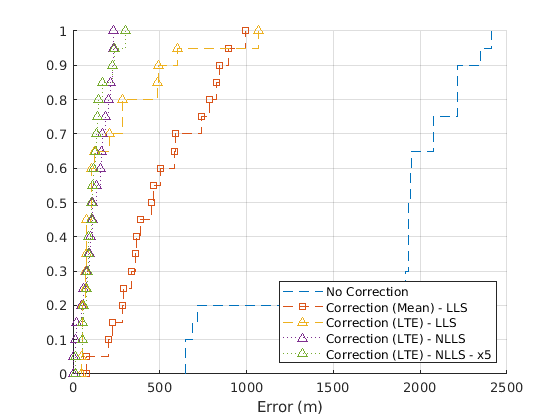

% Plotting
figure(); hold on; grid on;
stairs(dphase_1_0_0.X_lls, dphase_1_0_0.F_lls, '--');
stairs(dphase_1_1_0.X_lls, dphase_1_1_0.F_lls, '--s');
stairs(dphase_1_1_1.X_lls, dphase_1_1_1.F_lls, '--^');
stairs(dphase_1_1_1.X_nlls, dphase_1_1_1.F_nlls, ':^');
stairs(dphase_10_1_1.X_nlls, dphase_10_1_1.F_nlls, ':^');
legend('No Correction', 'Correction (Mean) - LLS', 'Correction (LTE) - LLS', 'Correction (LTE) - NLLS', 'Correction (LTE) - NLLS - x5', 'Location','southeast');
xlabel('Error (m)');